% Configuración del puerto serie
port = 'COM8';  %Introducir puerto correspondiente a donde se conecta el equipo
baudrate = 115200;  % Velocidad de transmisión en baudios
ser = serialport(port, baudrate);
fopen(ser);

recorder1 = audiorecorder(44100,16,1,1);

%Lectura del fichero de instrucciones

instrucciones = char(lectura(nombreArchivo))

% Envio de la trayectoria, captura de la grabación y datos de la posición

[salida] = trayectoria_grabacion2(ser,instrucciones,recorder1);

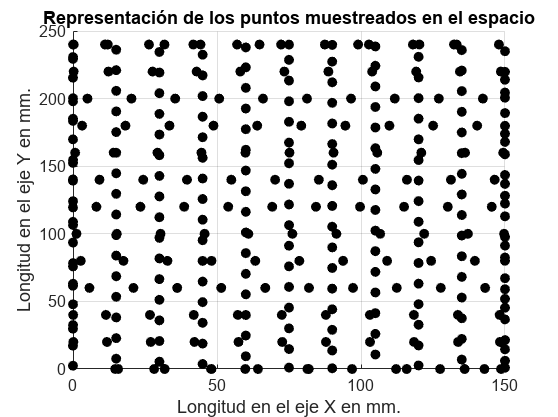

%Representación de la trayectoria 

scatter(salida(:,1),salida(:,2),'k','filled')
grid on
xlabel("Longitud en el eje X en mm.")
ylabel("Longitud en el eje Y en mm.")
title("Representación de los puntos muestreados en el espacio")

%Cálculo de la distancia entre los puntos capturados

for z=1:length(salida)-1
    distancia_puntos(z)=sqrt((abs(salida(1+z,1))-abs(salida(z,1)))^2+((abs(salida(1+z,2))-abs(salida(z,2)))^2));
end

%Cargar archivo grabado y procesado

[signal, Fs] = audioread("altavoz_4000hz.wav");
signal_raw = signal;
[samples, channels] = size(signal);
time = linspace(0,samples/Fs,samples);
signal = abs(signal);
muestras_original = 1:samples;

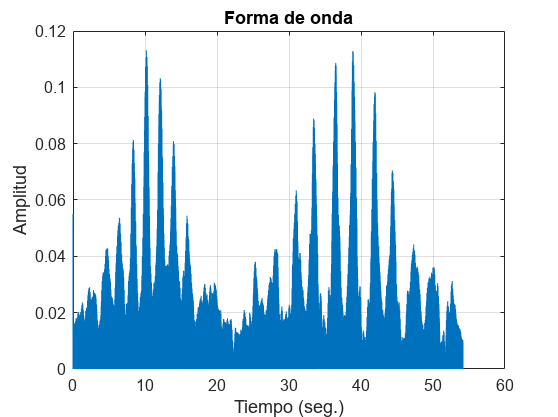

%Forma de onda de la señal grabada

plot(time,signal)
grid on 
title ("Forma de onda")
xlabel("Tiempo (seg.)")
ylabel("Amplitud")

pref = 10^-12;

% Calcular la potencia de la señal en unidades lineales
potencia_lineal = signal.^2;

muestra_anterior = 0;
fin_anterior = 0;

A_db = zeros(1,length(distancia_puntos));
for m = 1:length(distancia_puntos)   

    vel_media = ((salida(m,3)+salida(m+1,3))/(2)); % Cálculo de la velocidad media

    if vel_media == 0

        tiempo_trayectoria = 0;
    else
        tiempo_trayectoria = (distancia_puntos(m))/(((salida(m,3)+salida(m+1,3))/(2))/60); % multiplicamos por 60 para pasar la velocidad de mm/min a mm/seg
    end

    ventana =  floor(Fs*tiempo_trayectoria); % Tamaño de la ventana
    inicio = fin_anterior + 1; % Muestra de inicio de la ventana
    fin = ventana + fin_anterior; % Muestra de final de la ventana

    muestras = signal(inicio:fin);
    media_amplitud = (rms(muestras)); % Media rms de la ventana

    muestra_anterior = ventana;
    fin_anterior = fin;

    A_lineal(m) = media_amplitud;

end

pot_lineal = A_lineal.^2;
A_db = 10*log10(pot_lineal./pref);

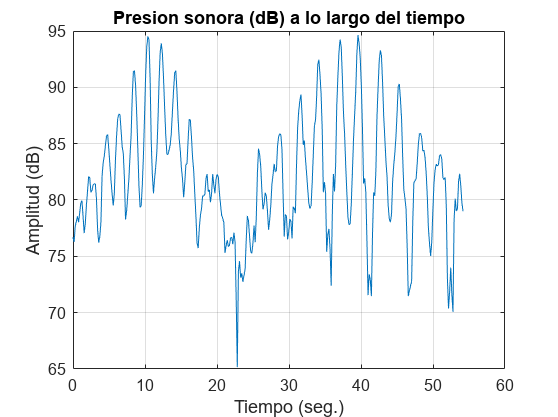

% Representación de los dB a lo largo del tiempo

t = linspace(0,samples/Fs,length(A_db));

figure
plot(t,A_db-2.5)
grid on 
title("Presion sonora (dB) a lo largo del tiempo")
grid on
xlabel("Tiempo (seg.)")
ylabel("Amplitud (dB)")

%Cálculo del tamaño de la matriz de datos

max_pos = max(salida, [], 1);
matriz_size_x = floor(max_pos(1) / max(distancia_puntos)) ; 
matriz_size_y = floor(max_pos(2) / max(distancia_puntos)) ; 

%Declaración de ejes para las representaciones espaciales

eje_x = linspace(0,max_pos(1),length(A_db));
eje_y = linspace(0,max_pos(2),length(A_db));

Análisis frecuencial con ventana equiespaciada

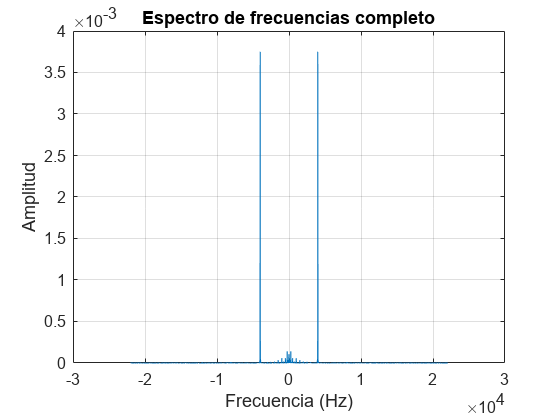

file = signal_raw;
fs = Fs;

% Asegurarse de que la señal sea un vector de columna (en caso de que sea estéreo, convertir a mono)
if size(file, 2) > 1
    file = mean(file, 2);
end

% Obtener el número de muestras
N = length(file);

% Calcular la FFT
Y = fft(file);

% Calcular el vector de frecuencias para el espectro completo
f = (-N/2:N/2-1)*(fs/N);

% Desplazar el espectro de frecuencia para que el cero esté en el centro
Y_shifted = fftshift(Y);

% Calcular la magnitud del espectro
magnitude = abs(Y_shifted)/N;

% Representar el espectro de frecuencias completo
figure;
plot(f, magnitude);
title('Espectro de frecuencias completo');
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
grid on;

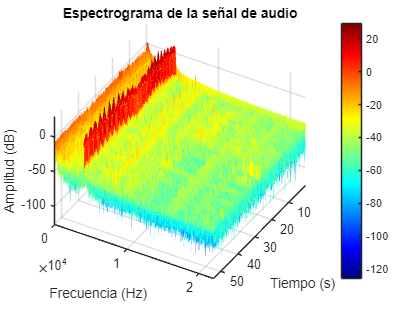

%Representación del espectrograma

% Configuración de parámetros del espectrograma

window_length = 1024;  % Longitud de la ventana
noverlap = 512;        % Número de muestras de superposición
nfft = 1024;           % Número de puntos FFT

[S_espec, F_espec, T_espec] = spectrogram(file, window_length, noverlap, nfft, fs);

%Representar el espectrograma en 3D
figure;
surf(T_espec, F_espec, 20*log10(abs(S_espec)), 'EdgeColor', 'none');
axis tight;
view(120,45);  
colormap(jet)
colorbar;  
xlabel('Tiempo (s)');
ylabel('Frecuencia (Hz)');
zlabel('Amplitud (dB)');
title('Espectrograma de la señal de audio');

%Procesado frecuencial

puntos = floor(length(signal)/length(distancia_puntos)); % Número de puntos de la ventana

ini_ventana = 1; % Inicio de la ventana
fin_ventana = puntos; % Final de la ventana

L = puntos; % Longitud de la señal

% Calcular el vector de frecuencias
f = fs*(0:(L))/L;

datos_frec = zeros(length(salida),2,puntos); % Declaración de la matriz tridimensional

for n=1:length(salida)-2

     datos_frec(n,1,1) = salida(n,1);% Indexamos los datos de posición del eje X
     datos_frec(n,2,1) = salida(n,2);% Indexamos los datos de posición del eje Y
     datos_frec(n,1,2:puntos+1) = ((fft(file(ini_ventana:fin_ventana))))'; % Indexamos los datos de la transformada de Fourier
     datos_frec(n,2,2:puntos+1) = ((fft(file(ini_ventana:fin_ventana))))'; % Indexamos los datos de la transformada de Fourier (mismos datos que antes)

    ini_ventana = fin_ventana+1; % Actualizamos inicio de ventana
    fin_ventana = puntos + puntos*n; % Actualizamos final de ventana

end

%Creación del mallado

[Xq, Yq] = meshgrid(eje_x, eje_y);

% Cargamos la imagen

altavoz2 = imread('altavoz2.jpg');

% Redimensionamos la imagen al tamaño de los datos
altavoz_recortado = imresize(altavoz2,[max(Yq,[],"all") max(Xq,[],"all")]);

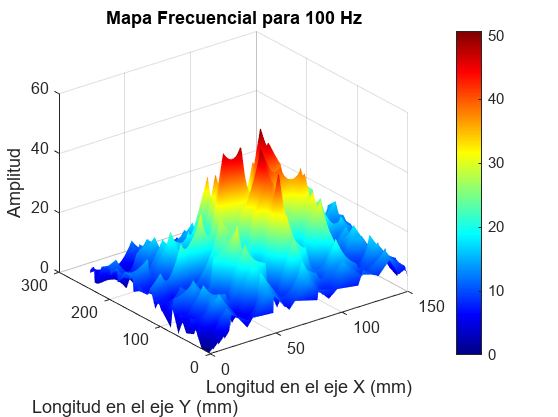

% Solicitar al usuario la frecuencia que desea analizar

frec_usuario = input('Por favor, ingrese la frecuencia (En Hz) que desea analizar: ');

valor_frecuencia = num2str(f(ceil((frec_usuario * length(f)) / fs)));

% Interpolar los datos (Interpolación natural)
Zq = griddata(salida(1:end,1), salida(1:end,2), abs(datos_frec(:,1,ceil((frec_usuario*length(f))/fs))), Xq, Yq,'natural');

%Representación tridimensional de la frecuencia en el espacio real
figure
S = surf(Xq,Yq,Zq);

titulo = sprintf('Mapa Frecuencial Barrido preciso del movil RMS ''cubic'' para %s Hz', valor_frecuencia);

titulo = sprintf('Mapa Frecuencial para 100 Hz');
title(titulo)
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")
zlabel("Amplitud")
colorbar
shading interp
colormap(jet)

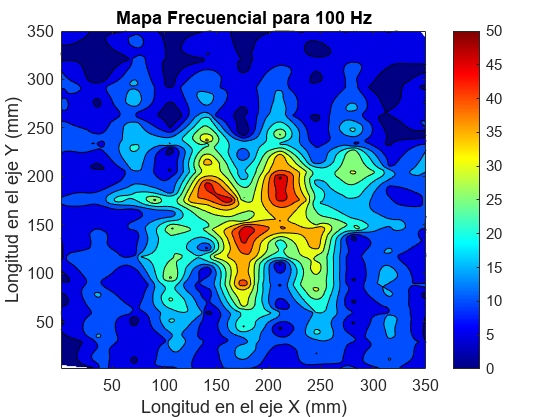


% Representación en dos dimensiones de la frecuencia en el espacio real
figure

S2 = contourf(Zq);

title(titulo)
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")
zlabel("Amplitud")
colorbar
colormap("default")
colormap(jet)

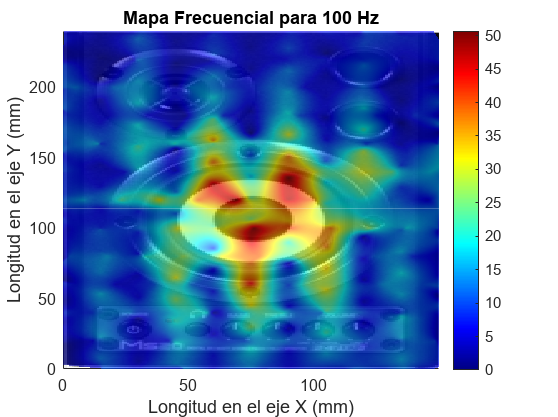


% Superposición del mapa en dos dimensiones con la imagen
figure
S_imag = surf(Xq,Yq,Zq);

title(titulo)
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")
colorbar
shading interp
colormap(jet)
S_imag.FaceAlpha = 0.6;
grid on
view([0 90])
xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(flip(altavoz_recortado))

hold off